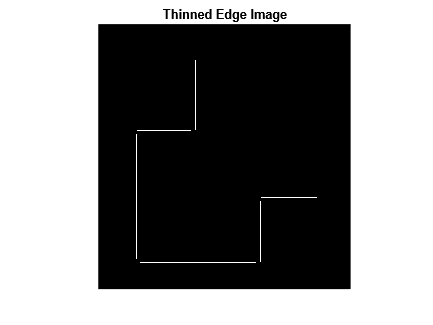

% Read the image
originalImage = imread('rotateddoublered.png');

% Detect edges and perform morphological thinning
[edgeImage, thinnedEdgeImage] = detectEdges(originalImage);

% Display the thinned edge image
figure;
imshow(thinnedEdgeImage);
title('Thinned Edge Image');


% Find boundary pixels and chain code
chainCode = traverseBoundaryWithCodes(thinnedEdgeImage);

% Display the chain code
disp('Chain Code:');

Chain Code:


disp(num2str(chainCode));

6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  6  5  6  6  6  6  5  0  0  0  0  5  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0

function [edgeImage, thinnedEdgeImage] = detectEdges(image)
    % Convert the image to grayscale if it's RGB
    if size(image, 3) == 3
        grayImage = rgb2gray(image);
    else
        grayImage = image;
    end
    
    % Detect edges using the Canny method
    edgeImage = edge(grayImage, 'Canny');
    
    % Perform morphological thinning to ensure one-pixel-wide boundary
    thinnedEdgeImage = bwmorph(edgeImage, 'thin', Inf);
end

function chainCode = traverseBoundaryWithCodes(thinnedEdgeImage)
    % Find the starting pixel (P0)
    [row, col] = find(thinnedEdgeImage, 1, 'first');
    startingPixel = [row, col];
    currentPixel = startingPixel;
    
    % Initialize direction
    DIR = 7;
    
    % Define directions
    directions = [0, -1; -1, -1; -1, 0; -1, 1; 0, 1; 1, 1; 1, 0; 1, -1];
    codeValues = [4, 3, 2, 1, 0, 5, 6, 7]; % Corresponding values for directions
    
    % Traverse the boundary
    chainCode = [];
    while true
        % Find the direction of the next white pixel
        nextDir = mod(DIR + 7, 8);
        found = false;
        for i = 1:8
            nextPixel = currentPixel + directions(nextDir + 1, :);
            if thinnedEdgeImage(nextPixel(1), nextPixel(2))
                found = true;
                break;
            else
                nextDir = mod(nextDir + 1, 8);
            end
        end
        
        % Break if the starting pixel is reached again
        if isequal(nextPixel, startingPixel)
            break;
        end
        
        % Assign the code value
        chainCode = [chainCode, codeValues(nextDir + 1)];
        
        % Move to the next pixel
        currentPixel = nextPixel;
        DIR = nextDir;
    end
    
    % Assign the code value for the starting pixel
    chainCode = [chainCode, codeValues(mod(DIR + 1, 8) + 1)];
end
